clear; clc; close all;
load fisheriris.mat;

X = meas(:, 3:4);
y = species;

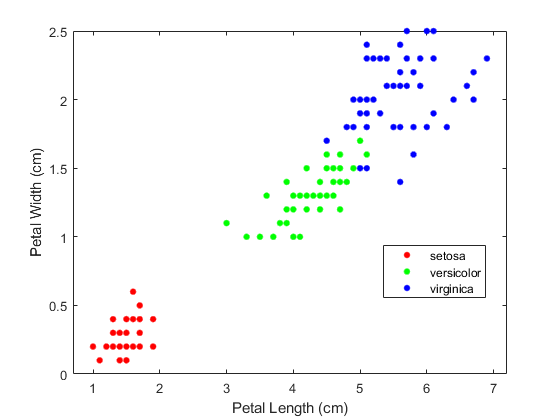

figure
gscatter(X(:,1),X(:,2),y);
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');

classes=unique(y);
SVMModels=cell(length(classes),1);

for j = 1:numel(classes)
    indx=strcmp(y,classes(j)); % Create binary classes for each classifier
    SVMModels{j}=fitcsvm(X, indx, 'ClassNames',[false true],'Standardize',true,...
        'KernelFunction','polynomial', 'PolynomialOrder', 9);
end

e=min(X(:,1)):0.01:max(X(:,1));
f=min(X(:,2)):0.01:max(X(:,2));
[x1 x2]=meshgrid(e,f);
x=[x1(:) x2(:)];
N=size(x,1);
Scores=zeros(N,numel(classes));

for j=1:numel(classes)
    [~,score]=predict(SVMModels{j},x);
    Scores(:,j)=score(:,2); % Second column contains positive-class scores
end

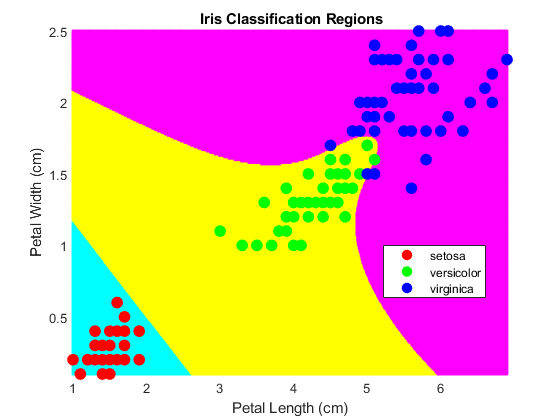

[~,maxScore]=max(Scores,[],2);

figure
gscatter(x1(:),x2(:),maxScore,'cym');
hold on;
gscatter(X(:,1),X(:,2),y,'rgb','.',30);
title('{\bf Iris Classification Regions}');
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');
axis tight
hold off

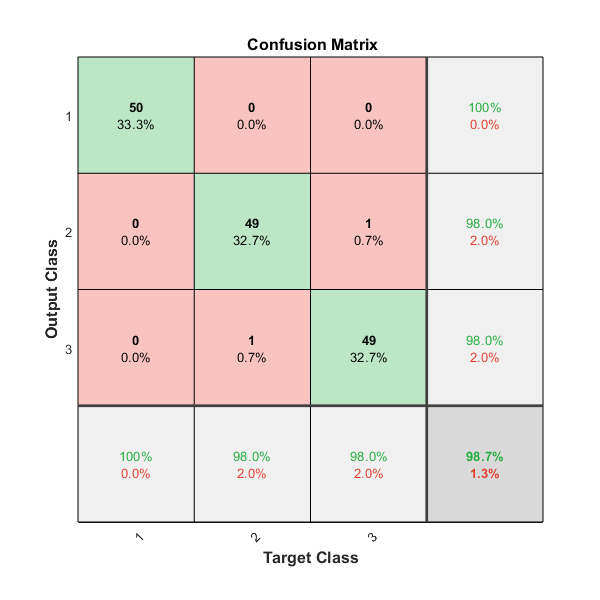

training_score = zeros(size(X, 1),1);
for j=1:numel(classes)
    [~,score]=predict(SVMModels{j},X);
    training_score(:,j)=score(:,2); % Second column contains positive-class scores
end

[~,maxScore_training]=max(training_score,[],2);

y_numerical = zeros(size(y, 1), numel(classes));
for j = 1:numel(classes)
    indx=strcmp(y,classes(j)); % Create binary classes for each classifier
    y_numerical(indx,j) = j;
end

plotconfusion(y_numerical', toCategorical(maxScore_training)');